# Hands-On -  ARMA(1, 1)  Stochastic Process: Correlation Function and the Spectral Power Density from Data 

## Introduction

Consider the process $ARMA(1,\,1)$ 


$$v(t) = \frac{1}{2} \, v(t-1) +  \eta(t)
+ \frac{1}{3} \eta(t-1) \, , \quad \eta(\cdot) \sim WN(0,\lambda^2)$$


or, equivalently


$$v(t) = \left[\frac{1 + \frac{1}{3}z^{-1}}{1 - \frac{1}{2}z^{-1}} \right]
\, \eta(t) = \left[\frac{z+\frac{1}{3}}{z-\frac{1}{2}} \right]\, \eta(t) = \frac{C(z)}{A(z)} \, \eta(t)$$


The **mean value** $\text{E}[v(t)]$ and the **variance** of the r.v. $v(t)$ are respectively


$$\bar{v} = \text{E}[v(t)] = 0 \qquad \qquad $$


The **spectral power density** is


$$\Gamma_{vv}(\omega) = 
\sum_{\tau=-\infty}^{+\infty} 
\gamma(\tau) e^{-j \omega \tau} \, = \frac{\left\vert C\left( e^{j\omega} \right) \right \vert^2}{
\left\vert A\left( e^{j\omega} \right) \right \vert^2} \cdot \lambda^2 = 
 \frac{\left \vert e^{j \omega}+\frac{1}{3}
\right \vert^2}
{\left \vert e^{j \omega}- \frac{1}{2}
\right \vert^2}  \cdot \lambda^2
= 
\frac{\left \vert
\cos \omega + j \sin \omega+\frac{1}{3}
\right \vert^2
}{\left \vert 
\cos \omega + j \sin \omega -\frac{1}{2}
\right \vert^2} \cdot \lambda^2
\qquad
\forall \, \omega \in [-\pi,\pi] $$


Thus, after some algebraic manipulation,


$$\Gamma_{v\,v}(\omega) = \displaystyle \left(\frac{
\frac{10}{9} + \frac{2}{3}
\cos \omega}{\frac{5}{4} - \cos \omega} \right) \cdot \lambda^2 \qquad
\forall \, \omega \in [-\pi,\pi] $$


## A Practical Issue

Suppose we acquire a finite number $N$ of samples from a WSS stationary ARMA(1, 1) process. How can we estimate the autocorrelation function and spectrum from the available data?

## Sampled Estimator of the Mean Value, the Variance and the Autocorrelation Function

We have already analysed the sampled estimators of mean value and variance. We recall them for convenience.

### Sample Average Estimator 

Given $N$ random variables $\, v(1)\,,\; v(2)\,,\; \ldots\,,\; v(N) \,$such that


$$\text{E} \left[ v(i) \right] = \mu_v\, , \quad i=1\,,\;2\,,\; \ldots\,,\; N$$


(i.e., with the same mean value) and						


$$\text{E} \left\{ \left[  v(i) - \mu_v \right] \, \left[ v(j) - \mu_v \right]\right\} = 0 \;, \quad \forall i \ne j$$


(i.e., the data are mutually uncorrelated), the **sampled-average estimator**					

				
$$\hat{\mu}_{v} = \displaystyle \frac{1}{N}\, \sum_{i=1}^{N} v(i) $$


is an **unbiased estimator**, i.e. 


$$\text{E} \left[ \hat{\mu_{v}}\right] = \mu_{v}$$


### The Sample Variance

The sample variance of $N$ observations $\{v_i\}, i=1,\ldots,N$ of the random variable $V$ with known mean $\mu_v$ is defined as 


$$ \hat \sigma^2_{\mu_v,N}={\frac {1}{N}}\sum _{i=1}^{N}(v_{i}-\mu_v)^2.$$


We have added the subindex $\mu$ to indicate that we used the exact value of the mean to calculate the variance. 

In practice, **the mean value is often unknown** and replaced by the sample mean. In that case the sample variance is defined as


$$ \hat \sigma^2_N={\frac {1}{N-1}}\sum _{i=1}^{N}(v_{i}-\hat \mu_N)^2$$


### The Sample Autocorrelation Function

Given $N$ observations $\{v_i\}, i=1,\ldots,N$ of the random variable $V$ with **null mean value** $\mu_v = \text{E}\left[ v_i \right] = 0 \; \forall i$, the autocorrelation function $\gamma_{v}(\tau)$ can be estimated by mean of the following expression


$$\hat{\gamma}_v (\tau) = \left\{ \begin{array}{lcl}
\displaystyle \frac{1}{N-\tau} \sum_{n=0}^{N-\tau-1}\, v(n)\cdot v(n+\tau) & \quad & \tau \ge 0 \\
\hat{\gamma}_v(-\tau) & \quad & \tau <0
\end{array} \right. \qquad \left| \tau \right| \le N-1$$


It can be proven that it is an **unbiased estimator **(refer to [1] for details). Moreover, it can be proven that the variance of the estimate converges to zero as $N \to \infty$, so the estimate $\hat{\gamma}(\tau)$ is a **consistent estimate** of $\gamma(\tau)$ (refer to [1] for details).

## Estimated Autocorrelation Function from Data

Let us generate $N$ samples of a WSS stationary MA(1) stochastic process, with zero mean and variance $\lambda^2$.

Collect the data and then apply the sampled estimators.

clear variables
close all
clc

### Generate and Collect the Samples

Remember


$$ARMA(1,\,1) \, \colon \quad v(t) = \frac{1}{2} \, v(t-1) +  \eta(t)
+ \frac{1}{3} \eta(t-1) \, , \quad \eta(\cdot) \sim WN(0,\lambda^2)
$$


To wash out the transient response, consider to generate $N_{skip}+N_{data}$ samples fo the stochastic process and then to throw out the first $N_{skip}$ samples, keeping only the steady-state behaviour (so the stationary stochastic process).

Ndata = 65000;    % select how many samples to collect and store
Nskip = 2500;      % how many samples to generate, but then ignore?

Ntot = Nskip+Ndata;                      % total num. of samples to generate

% -------

varWG = 1;      % select the white noise variance

eta = sqrt(varWG)*randn(Ntot,1); % let's generate the white noise samples


% ---- the array to store the samples of the stochastic process ----

ARMA1_1 = zeros(Ndata,1);    % preallocating the store for the samples 
                             % for the "v(t)" array for the ARMA(1, 1)
                             % process

a1 = 1/2; % the parameters of the ARMA model
c1 = 1/3;
% ------------------------------------------------------------------


N_init = 1;               % the number of initial conditions, needed 
                          % to initialise the generation of an ARMA(1,1)
                          % process realization                                                     
v_init = randn(N_init,1); % the initial condition for the  process                                                    
                                                     

### The ARMA(1, 1)  Stochastic Stationary Process

Let's generate the data from the ARMA(1,1) process

% --- let's generate a realization for the process

% the buffer to store the transient behaviour of the stochastic process
buffer = zeros(Nskip,1); % a buffer used to generate a stationary process, 
                         % regardless of any possible initial condition
buffer(1:N_init) = v_init;     % the initial condition for the process


ARMAbuffer = [buffer; ARMA1_1]; % merging the arrays

% ---- the ARMA process ----
for ii = (N_init+1):Ntot
    ARMAbuffer(ii) = a1 * ARMAbuffer(ii-1)+ eta(ii)+c1*eta(ii-1); 
    %                ^^^^^^^^^^^^^^^^^^^^^          ^^^^^^^^^^^^
    % se ho ordine due AR modifico qua                    se ho ordine due per MA, qua
end % for ii

ARMA1_1 = ARMAbuffer(Nskip+1:end); % let's throw away the transient part 
% of the process evolution, in order to "forget" the initial conditions


Let's estimate the **mean value** and the **variance** for the AR(2) process. 

av_valARMA = mean(ARMA1_1)      % the average value for the AR process

av_valARMA = -0.0125

var_ARMA = var(ARMA1_1)

var_ARMA = 1.9264

Run more than once, varying the variance of the process. Observe the convergence of the sampled estimates of the mean value and the variance to the effective values, when increasing the number of collected data.

### **What About the Autocorrelation Function?**

#### **Estimation of the Autocorrelation Function**

Ncorr1 =1024; % select the max value of tau in the estimation formula

Check if the maximum value for the lag $\tau$ is respecting the constraint $|\tau| \le N-1$, with $N$ the amount of available data.

errMSG = 'The max lag must be less or equal to (N-1), with N the amount of available data!'; % error message
assert((Ncorr1 <= (Ndata-1)), errMSG)

Let evaluate the estimate, using the MATLAB command `xcorr().`

Have a look to the command input and output variables, and to some application examples, using 


[gamma_ARMA, lags_ARMA] = xcorr(ARMA1_1, Ncorr1,'unbiased'); 
% unbiased estimation of the autocorr. function


Now let's plot 

- the acquired samples of the ARMA process

- the samples of the estimated autocorrelation function

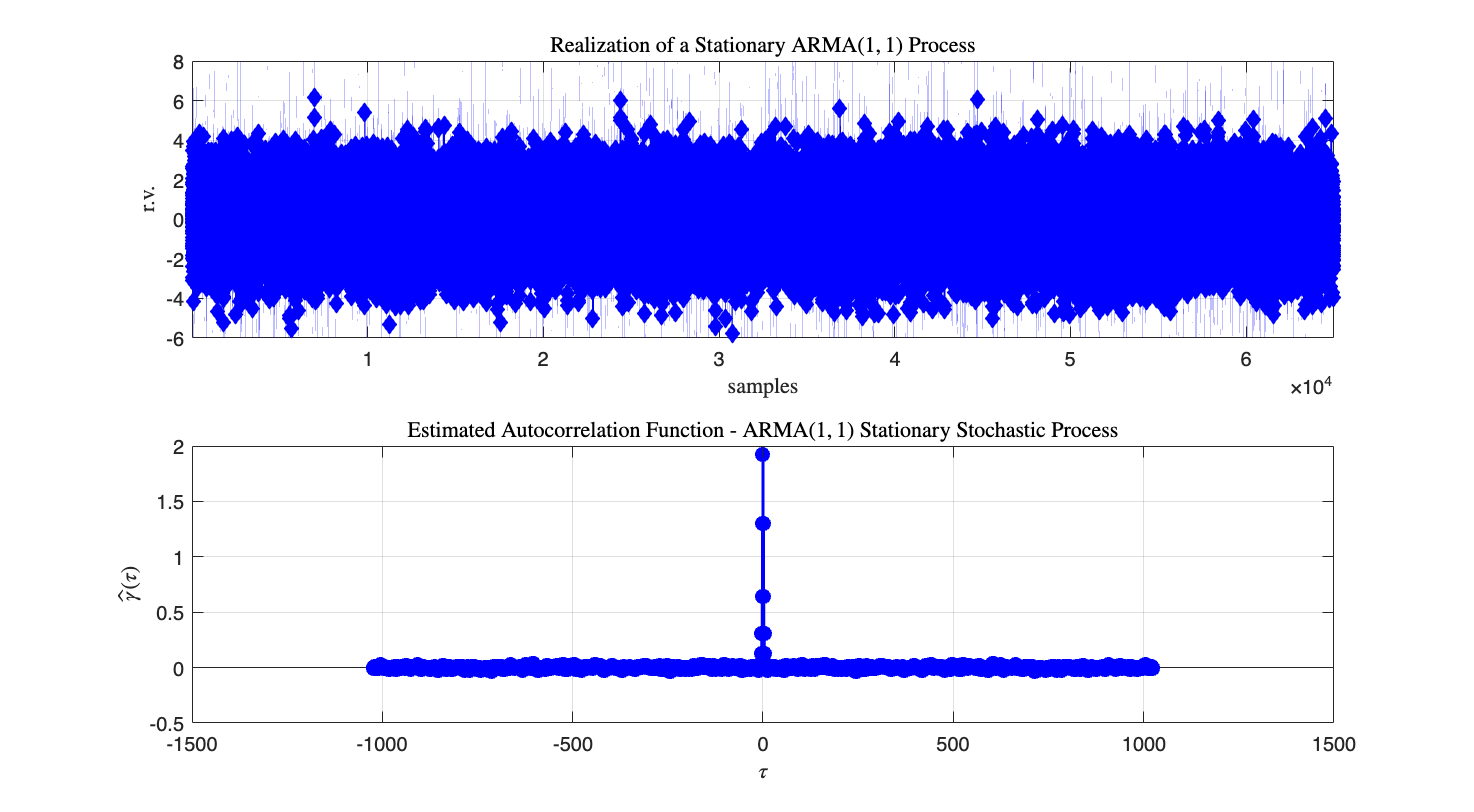

figure('Units','normalized','Position',[0.1, 0.1, 0.85, 0.75]);

subplot(2,1,1);
plot(ARMA1_1,'db-','MarkerSize',6, 'MarkerFaceColor','b','LineWidth',1.0);grid on;
title('Realization of a Stationary ARMA$(1, 1)$ Process', 'Interpreter','latex');
xlabel('samples', 'Interpreter','latex');ylabel('r.v.', 'Interpreter','latex');
xlim([1, Ndata]); % setting the extremum values on the x-axis

subplot(2,1,2);
stem(lags_ARMA, gamma_ARMA,'b','filled', 'LineWidth', 1.5);
grid on; hold on; % the estimated autocorerlation function

xlabel('$\tau$', 'Interpreter','latex');ylabel('$\hat{\gamma}(\tau)$',...
    'Interpreter','latex');
title('Estimated Autocorrelation Function - ARMA$(1, 1)$ Stationary Stochastic Process',...
    'Interpreter','latex');

## Estimation of the Spectral Power Density from Data 

So far, we estimated the average value, the variance of the r.v. of the process and the autocorrelation function, just using the collected data. What about the **spectrum**?

Given the samples of the estimated autocorrelation function $\hat{\gamma}(\tau)$, the **estimate of the spectrum** can be evaluate  according to the so-called ***"periodogram"***** algorithm**

### Spectral Power Density Estimation: the Periodogram - A Recap

Given $2N-1$ samples of the autocorrelation function $\hat{\gamma}(\tau)\,,\quad \tau = -N+1\,,\; -N+2\,,\; \ldots\, N-2\,,\; N-1$, where $N$is the number of collected samples of the r.v.

- the Fourier transform of the autocorrelation function estimate is

$\hat{\Gamma}(\omega) = \displaystyle \sum_{\tau=-(N-1)}^{N-1}\; \hat{\gamma}(\tau)\,e^{-j\omega\,\tau}$    (++)

- by substituting into $\hat{\Gamma}(\omega)$ the expression of $\hat{\gamma}(\tau)$ as function of the samples $v(n)$, and taking into account the properties of the autocorrelation function (the correlation function is an even function), the estimate $\hat{\Gamma}(\omega)$ can also be expressed as

$\hat{\Gamma}(\omega) = \displaystyle \frac{1}{N} \left\vert  \sum_{n=0}^{N-1}\, v(n)\,e^{-j\omega\,n} \right\vert^{2} = \displaystyle \frac{1}{N}  \left\vert \hat{V}(\omega) \right\vert^{2} $  where $ \hat{V}(\omega) = \displaystyle \sum_{n=0}^{N-1}\, v(n)\,e^{-j\omega\,n} $    (*)

- It can be proven  that the expected value of the estimated spectrum is a **smoothed version of the true spectrum**. Moreover, it suffers from the same **spectral leakage problems** which are due to the finite number of data points (refer to [1] for details). Hence **the periodogram is not a consistent estimate** of the true power density spectrum.

- Over the years, many other methods have been proposed, with the aim of obtaining a consistent estimate of the power spectrum, but these algorithms are outside the scope of this live script (and these topics are not included in the course). For details, please refer to a textbook on "Digital Signal Processing" such as [1].

#### The Algorithm: Using the DFT in Power Spectrum Estimation

- given $N$ samples of the r.v. $v$, evaluate $ \hat{V}(\omega) = \displaystyle \sum_{n=0}^{N-1}\, v(n)\,e^{-j\omega\,n} $, using the DFT algorithm, or more efficiently the FFT algorithm;


$$\hat{\Gamma}\left( 2\pi \displaystyle \frac{k}{N} \right) = \displaystyle \frac{1}{N} \left\vert  \sum_{n=0}^{N-1}\, v(n)\,e^{-j\,2 \pi \,n\,\frac{k}{N}} \right\vert^{2} \qquad k = 0\,,\;1\,,\;2\,,\;\ldots N-1$$


#### The Spectrum of the ARMA Process

Given the samples, collected in the `array gamma_ARMA`, let's apply the Eq. (++) to estimate the spectrum:

- Evaluate the DFT of the autocorrelation function estimate sequence

ARMA_FFT = fftshift(fft(gamma_ARMA));   % compute the FFT of 
                                     % the autocorrelation function samples
                                     % sequence

% rearrange the array of the FFT, by shifting 
% the zero-frequency component to the 
% center of the array.

- Compute the power spectrum estimate according to Eq. (++)


$$\hat{\Gamma}(\omega) = \displaystyle \sum_{\tau=-(N-1)}^{N-1}\; \hat{\gamma}(\tau)\,e^{-j\omega\,\tau}$$


**Proposal**: perform the spectrum estimation according to Eq. (*) [the periodogram] and compare the results.

powerSpectrumARMA = abs(ARMA_FFT); 
% the squared magnitude of the Fourier transform


- Compute the corresponding angular frequencies

omegaPSD = linspace(-pi,pi,numel(gamma_ARMA)); 
% (2 pi)/Ndata is the angular frequency resolution for the spectrum

z = tf('z', 1); % let's define a discrete-time transfer function W(z) = 1/A(z)
Wz = (z+c1)/(z-a1) % the linear system, feeeded by the white noise process, describing the AR process

Wz =
 
  z + 0.3333
  ----------
   z - 0.5
 
Sample time: 1 seconds
Discrete-time transfer function.
Model Properties



Wejomega = abs(freqresp(Wz, omegaPSD));
Wejomega = reshape(Wejomega, [1, numel(omegaPSD)]); % reshaping Wejomega --> from 3d-array to 1d-array

% Mi aspetterei che freqresp mi dia un array di valori, ma in realta`
% risponde con un array 3d che devo reshapare per scartare 2 dimensioni

W_ejom2 = Wejomega.^2; % the squared magnitude of the frequency response of W(z)

PSDtrue = W_ejom2 .* varWG; 
% the theoretical spectrum, evaluated at the angular frequencies in omegaPSD

- plotting the spectrum and compare with the theoretical expression $\Gamma_{vv}(\omega) = 
\sum_{\tau=-\infty}^{+\infty} 
\gamma(\tau) e^{-j \omega \tau} \, = \frac{\left\vert C\left( e^{j\omega} \right) \right \vert^2}{
\left\vert A\left( e^{j\omega} \right) \right \vert^2} \cdot \lambda^2
\qquad
\forall \, \omega \in [-\pi,\pi] $

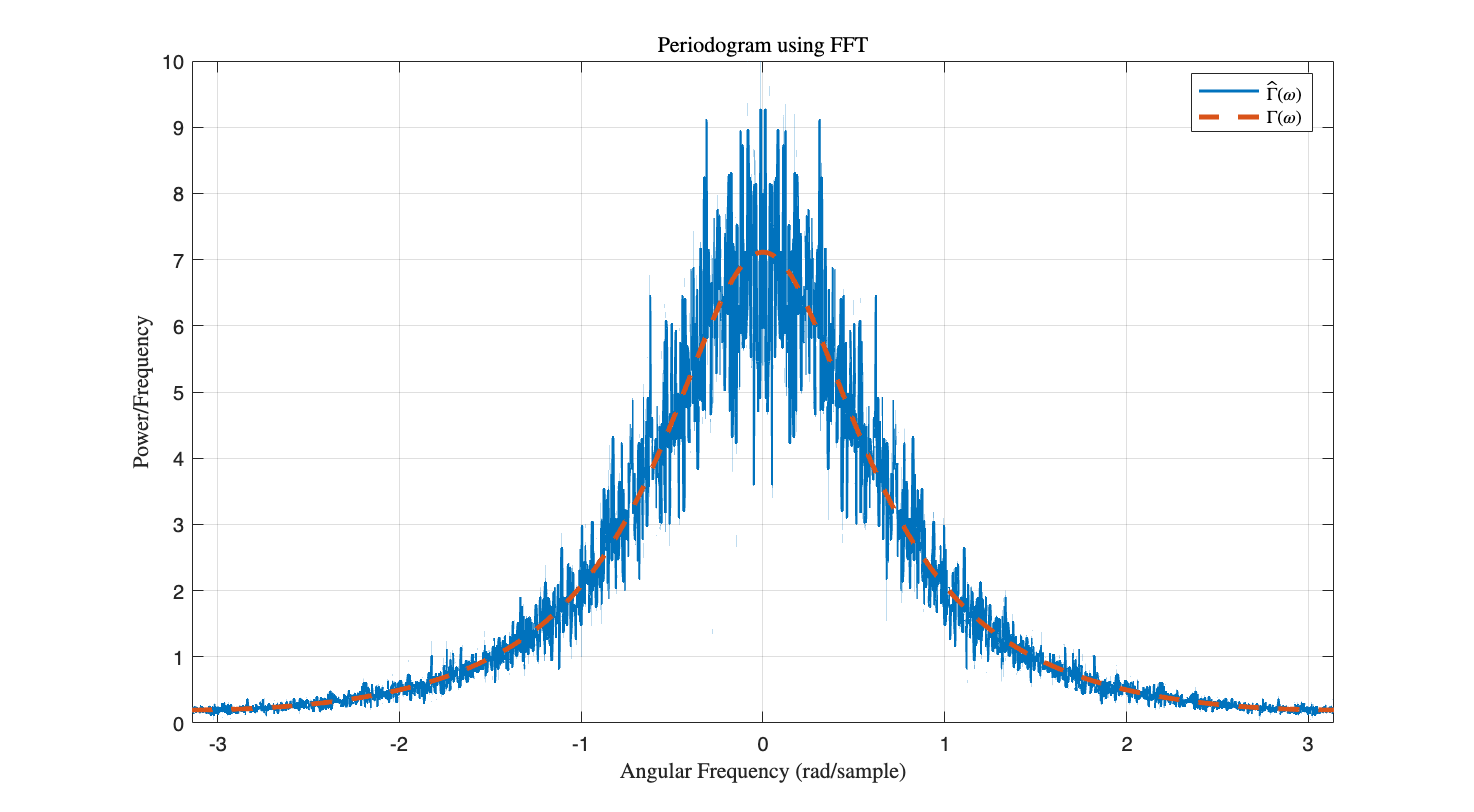

figure('Units','normalized','Position',[0.1, 0.1, 0.85, 0.75]);
plot(omegaPSD,powerSpectrumARMA, 'LineStyle','-','LineWidth',1.5); % the estimated PSD
xlim([-pi, +pi]); % setting the extrema on the x-axis
grid on; hold on;
plot(omegaPSD,PSDtrue, 'LineStyle','--','LineWidth',2.5); % the estimated PSD
xlabel("Angular Frequency (rad/sample)", 'Interpreter','latex');
ylabel("Power/Frequency", 'Interpreter','latex');
title("Periodogram using FFT", 'Interpreter','latex');
legend('$\hat{\Gamma}(\omega)$', '$\Gamma(\omega)$', 'Location','best', 'Interpreter', 'latex')

#### **Remark**

As written above, the periodogram is an estimate that can be very rough. Compare with the theoretical spectrum.

## References

[1] Proakis, John G. and Manolakis, Dimitris K.  * Digital Signal Processing (3rd Edition),* Prentice Hall,  1996.  